# Wireless Final Project

**Hamidreza aliakbary khoyi - 810196514**

## **introduction**

The aim of this project is to design an OFDM system by implementing it block by block based on the block diagram given in the block diagram, comparing AWGN and Riley channels, the effect of the identifier on the probability of bit detection error (BER) and finally range detection. The OFDM message is with the help of specified Pilot signals. The whole operation of this system is based on dividing a message into several frames and dividing each frame into sections, each of which is placed on a subcarrier. For this reason, the OFDM system is a subset of multicarrier systems. The main feature of this system is to determine the frequency of the carriers in such a way that the filter spectrum of each sub-channel in the passage of time in the location of the central frequency of the adjacent sub-channel exceeds zero. To fulfill the above condition, the sub-carriers must be at least 1/1 T apart. For this reason, this system is called Orthogonal Frequency Division Multiplexing or OFDM for short.

## **Part A**

## Block Definition

# Transmitter

Initially, the data is generated randomly using the randi function and takes the form of a string of bits, both bits of which are placed next to each other (originally stored as a matrix). This storage method prepares them to become symbols corresponding to the QPSK signal space.

## QPSK Modulator

This module is responsible for depicting even pairs of bits in decimal numbers in the range of 0-3. The symbols of the image space in this map are placed next to each other based on Gray Coding to minimize the bit error for a certain symbol error. In the case of the project, it is stated that the input size given to the system is a message with a length of 10^ 7 bits, which, considering that we use a 4-bit modulation and both bits are represented as a symbol in the mixed space, The length of the message will be 5 × 10^ 6 symbols. After the incoming message in this module became a matrix with dimensions of 500000 × 2. Each of the columns in this matrix represents a pair of bits that are put together in the main message. After passing this module, these pairs of bits are mapped to the corresponding number according to the assigned Gray Coding. Therefore, the output of this module will be a vector of length 5 × 10^ که 6, which contains the numbers 0-3.

## Frame Divider

Since it is not appropriate to send all the messages at once (due to re-sending problems due to errors, etc.) in the OFDM system, each message is divided into several frames and the frames are sent separately (although Here only the data structure is changed and all the frames are sent together for convenience).The number of frames should be calculated based on the number of symbols in each frame (capacity of one frame). This number is given by the fact that we have several subcarriers (nc) and each subcarrier has the capacity of several symbols (sfc). The product of these two numbers will show the total capacity of each frame based on the symbol. Thus, by separating each 8400 batch from the output module of the previous module, the Frame divider module will separate 595 full frames and one incomplete frame. Add zero to the end of the last frame to output 596 data frames for the next blocks. The output of this module will be the number of frames or the size of each (it is enough to have a standard output to separate the data according to that criterion, the next module that changes the data structure).

## Serial to parallel

Finally, the storage form of these frames can be in two ways.

1- Each frame should be stored as a 21 by 400 matrix and the matrices should be put together and sent.

2- Each frame should be placed as a layer between two adjacent frames as a matrix so that the whole data is in the form of a tensor whose dimensions are 21 by 400 by 596

In this implementation, the second method is used to store the data because of its more orderly form and the advantages that the tensor data structure has for reshaping the next blocks. For this reason, this storage format is called framing parallelism.

## DPSK Modulation

It will be a function of the distance of consecutive symbols in the input sequence. Every return relationship needs an initialization condition to be established. Here a symbol is added to the beginning of each column (as the initial symbol for the string of symbols of each subcarrier) that this value of the symbol has no effect on the final retrieval so we select it randomly.

So it 's like adding a random row as a reference row to the beginning of each layer (matrix, frame) of this tensor, or adding a layer equivalent to the top of this tensor as a reference layer for DPSK modulation.

The output of this module according to the above description will be a tensor with dimensions of 22 by 400 by 596.

## IFFT Bins allocation

The OFDM system is based on sending symbols in the time domain, but since some filters, such as Equalizer filters, perform better in the frequency domain, the modules before and after the time domain modules should be in the frequency domain and the initial modulation And message structuring in them. A module is also needed to convert the symbols from the frequency domain to the time domain, which is the IFFT module, the number of points of which is proportional to the IFFT accuracy taken. The corresponding module in the receiver that returns the symbols to the frequency domain is the FFT module. In this project, the number of points of these two modules is 1024 points. Given that each subcarrier represents a central frequency in its own frequency range, IFFT and FFT should be taken in line. Therefore, the number of columns of the input matrix to this module and the output matrix of the FFT module should be 1024. In order not to change the result and the output in the realm of time to be real, we put the conjugate block of each frame next to it. inadvertantly begining and end of matrix columns has 50 zero columns and others has remained in middle.

## CP Addition

In order to be able to multiply the properties of the system convolution in the time domain to the multiplicity property in the frequency domain, the performed convolution must be equivalent to an annular convolution. And the mentioned condition is established automatically if one of the cannulated signals is circular (the end part of it is repeated at the beginning or vice versa). In order to provide such a space for a part of the signal to be placed at the beginning of the frames, guard bands in the time axis are considered in which the real data is not sent, and the same prefix is ��either zero prefix or cyclic. send prefix in this interval. The main goal of guard bands, but as mentioned during the lesson, to prevent interference between symbols under the same carriers of adjacent blocks (inter-block interference) and also to prevent out of band radiation (out of band radiation) According to the specified CP ratio, several columns should be added to the beginning of each frame (matrix), here the cp ratio is equal to 1.4, because the end 25% of each row should be added to the beginning and the output tensor of this dimensional module It will have 22 by 1280 by 596. (256 columns added to the beginning of each frame) The CP ratio, which is also the direct overhead ratio of the system, can be defined as a variable and increased or decreased.

## Parallel to serial

After the IFFT operation is performed on the data and the rotation prefix is added at the beginning of each frame, we are going to send the frames one after the other. First we make each matrix (frame) as a vector. It should be noted that the columns of this matrix should be placed behind each other because the whole CP part is next to each other in the project form (with the phrase frame guard). After passing through this module, each of the frames will be in the form of vectors that are arranged in a row below. (Convert tensor to matrix)

## Cascade Frames

At this point, all 596 frames, each of which has become a vector and the beginning of each of which forms a circular prefix, are stacked on top of each other and placed in a ready-to-send vector. (Convert matrix to vector) In addition, this module is responsible for adding two headers to the beginning and end of the data. The length of the headers will be 8 times the length of each frame (of course, the original frame and not with the frame guard), which is equivalent to:

Symbol according to header length = 22 × 1024 × 8 = 180224 (symbol)The content of the headers for the score section can be considered a pilot signal (occupying only the beginning of the header)

## Clipping

Due to the use of amplifiers that enter the saturation zone at relatively high amplitudes, the transmitted signal is nonlinearly distorted relative to the different amplitudes before being placed on the channel. This nonlinear effect usually occurs by clipping the amplitudes in the signal if they are above a certain threshold. This threshold is given relative to the maximum amplitude of the symbols sent in the 3dB project, which is used as a variable at the end of the transmitter function and can be changed.

# Channel

To model the channel, we use either a simple AWGN noise or a combination of AWGN noise at the beginning of the receiver and multiplying a random Riley before it. We store the Riley random variable with variance 1 as the channel fading coefficient in the vector corresponding to the fading coefficients, and multiply it by the signal coming out of the transmitter output.

# Receiver

First, the received vector symbol is divided into frames made in the transmitter (the number of frames, which is 596, is also specified in the receiver (based on sfc, nc) and thus, each of the separated parts is divided into The title of one frame is placed below another (line segmentation), so the output of this module is a 596 in (2280 × 1280) matrix. It should be noted that before separating, we must discard the symbols as much as the header length. The header length can be calculated similar to the one stated in the transmitter or given as a direct number to the receiver.

## Serial to Parallel

The rows of input matrices to this module are each a form and must be re-matrixed so that subsequent operations such as removing the prefix and FFT can be applied to it in rows (as the corresponding modules in the receiver did) to retrieve each symbol. Do it correctly (finally compare each symbol with your own estimate of that symbol and not another symbol)

So this module divides each row into 22 categories (SFC + 1 (ref)) and then sorts the categories into a matrix. In addition, it lays each of the resulting matrices, which represent a frame, in layers so that the data takes the form of a tensor (converting the matrix to a tensor).

## CP Removal

In this section, 256 symbols added to each row (a total of 256 primary columns) of each frame will be set aside and the original frames will be placed in the same tensor shape along the path. Therefore, the output of this module will be a tensor with dimensions of 22 by 1024 by 596.

## FFT

At this stage, the frames are taken as a 1024-point Fourier transform in series and the output is given to the next module to separate the original frame.

## Extract Carriers from FFT bins

The columns that formed the main frame are separated according to the way they are placed in the corresponding module in the receiver. (From columns 76 to 475)

## DPSK Demodulation

An important operation that must be performed in this module first is the detection of symbols. This is because the DPSK Demodulation input recognizes the same mixed symbols that the corresponding module generates, and a noise signal will naturally be at a certain distance from these constellation points in the signal space. So either we have to calculate the distances to the points and the point that has the least distance with the noise signal image in the signal space (mixed space) is selected as the detector estimate. Or it should be made using the determination of decision areas that for DPSK modulations the most basic task is to convert the polar coordinates and make decisions based on the range in which the phase is located. DPSK modulation is then performed in this module. Each column with a reference symbol at the top XOR gathers two consecutive symbols in the same way and replaces the result. Thus, the output tensor will have dimensions of 21 by 400 by 596. This removes the added reference row.

## Parallel to Serial

Once again, we turn the data tensor into a matrix. In other words, we flatten each of the frames and place them below in rows of a matrix with dimensions of 596 by 8400.

## Cascade Frames

In order to be able to compare the detector estimates with the original symbols in a peer-to-peer manner, it must all be in the form of a vector, so once again, this time in the receiver, we stack the rows (frames) of the data matrix. The output of the module will be a symbol string with a length of 5*10. ^ 6.

## QPSK Demodulation

In this step, return the symbols that are defined in decimal according to the same gray coding to the original bit pair. The output vector will be a bit string with the same length 〖10 ^ که 7 that is ready for comparison and calculation of BER.

## BER Calculation

In the last part, it is enough to form the evaluation vector. A vector whose element is equal to the corresponding elements of the estimation vector and the vector of the initial bit string is 1 and otherwise 0. Finally, the sum of the 0s indicates the number of false bit detections, and if we divide this value by the total length of the bit string, we get the BER corresponding to the generated bit string. 

Generating random bit sequence

total_bits = 10^7;
M = 4;
total_symbols = total_bits/log2(M);
rand_bit = randi([0 1], total_symbols, log2(M));

ber = OFDM(rand_bit, 400, 1024, "True", "False", "False", 20, "AWGN", 3)

ber = 0.4979

## Part B

ber = zeros(1,30);
for i = 2:2:60
    [ber(i/2), ~] = OFDM(rand_bit, 400, 1024, "True", "False", "False", i, "AWGN", 3);
end
%bit_sequence, no_carriers, IFFT_length, clippingmode, delayed_mode, eqz_mode, SNR_db, channel_mode, varargin

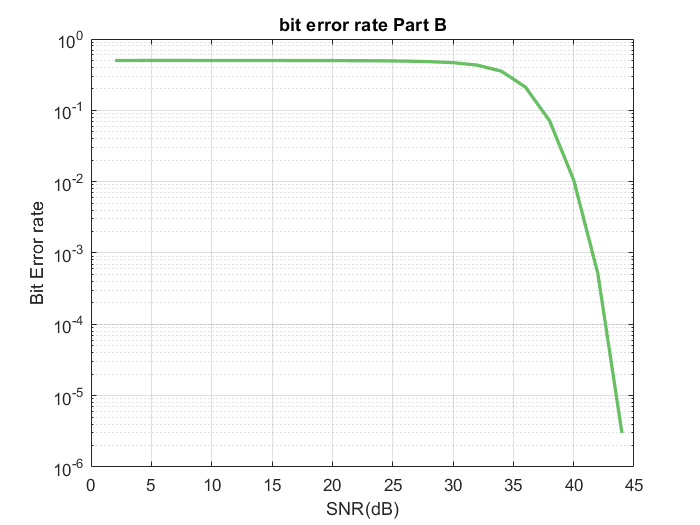

plot_enhanced(2:2:60, ber, "SNR(dB)", "Bit Error rate", "bit error rate Part B")

## Part C

If we plot the probability of a bit error in terms of the clipping level due to the nonlinear (saturating) effect of the overload power amplifiers, we see an upward behavior which is also expected because as the size of this clipping increases (or Symbols with lower amplitudes are also distorted, and as the total number of symbols distorted and then placed on the channel increases, the probability of false detection and bit error increases.

Note: By choosing SNR=20dB desired behaviour of increasing clipping wont be schived, thus i chose 40 db.

ber = zeros(1,20);
for i = 1:20
    [ber(i), ~] = OFDM(rand_bit, 400, 1024, "True", "False", "False", 40, "AWGN", i);
end

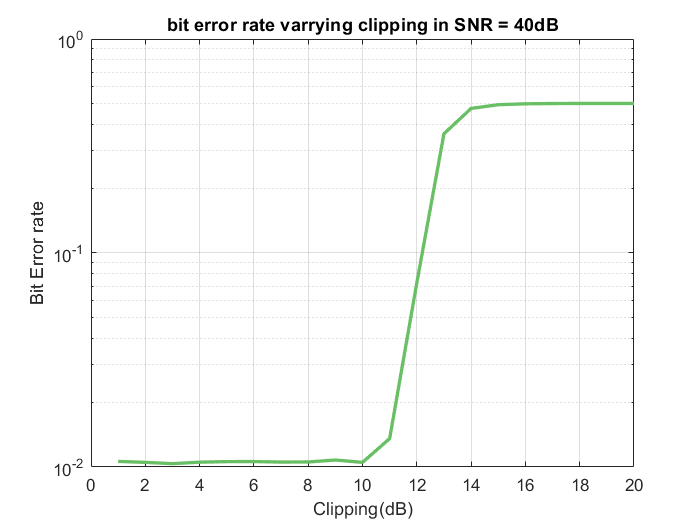

plot_enhanced(1:20, ber, "Clipping(dB)", "Bit Error rate", "bit error rate varrying clipping in SNR = 40dB")

## Part D

ber_neq = zeros(1,25);
for i = 2:2:50
    [ber_neq(i/2), ~] = OFDM(rand_bit, 400, 1024, "True", "False", "False", i, "Rayleigh", 3);
end

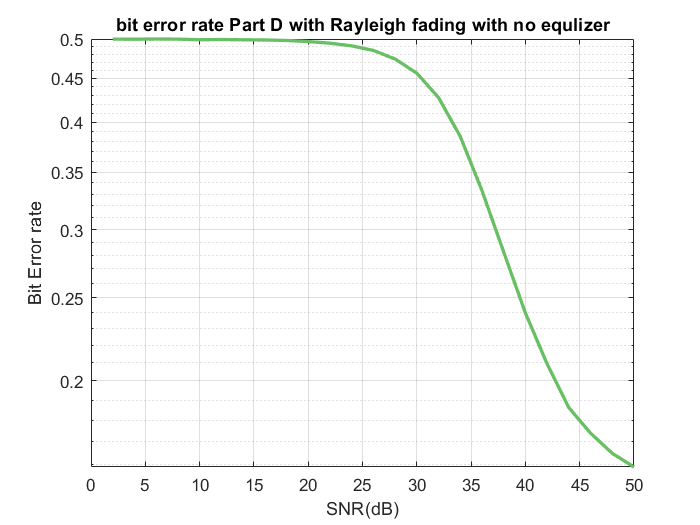

plot_enhanced(2:2:50, ber_neq, "SNR(dB)", "Bit Error rate", "bit error rate Part D with Rayleigh fading with no equlizer")

## Part E

ber_eq = zeros(1,25);
for i = 2:2:50
    [ber_eq(i/2), ~] = OFDM(rand_bit, 400, 1024, "True", "False", "True", i, "Rayleigh", 3);
end

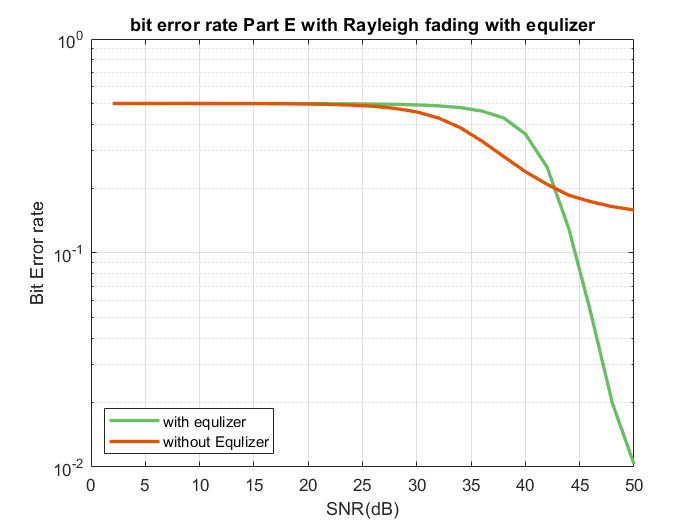

plot_enhanced(2:2:50, ber_eq, "SNR(dB)", "Bit Error rate", "bit error rate Part E with Rayleigh fading with equlizer", ber_neq, ["with equlizer" "without Equlizer"])

To model this type of channel, we generate a Riley random variable with variance 1 and sample it. Repeat this as many symbols as possible and store it in a vector that represents the channel hit response. (We consider the channel to be the same length as the original signal for simplicity.) As expected, the bit error corresponding to the Riley channel is higher than the AWGN channel. It also appeared that the Riley channel error would be reduced to a minimum and would not be significantly reduced by increasing the SNR overnight. The important point is to first multiply the Riley coefficient and then model the AWGN noise as a station process at the beginning of the receiver (end of the channel).

According to the relation mentioned in the lesson for this calculation of the coefficients of this identifier, we calculate its coefficients at the beginning of the receiver in a section related to the identifier, and then multiply by the symbols of the symbols on the channel. As it turns out, the probability of a bit error for a receiver with an MMSE synchronizer, whose coefficients are converted to Hk in high SNRs, is lower than the SNR, and the low limit that appears in Riley's blur is no longer observed.

## Part F(Bonus)

Bonus_ber = OFDM(rand_bit, 400, 1024, "True", "True", "False", 20, "AWGN", 3)

Bonus_ber = 0.4983

repeating part B for Bonus:

bonus_ber = zeros(1,30);
for i = 2:2:60
    [bonus_ber(i/2), ~] = OFDM(rand_bit, 400, 1024, "True", "True", "False", i, "AWGN", 3);
end

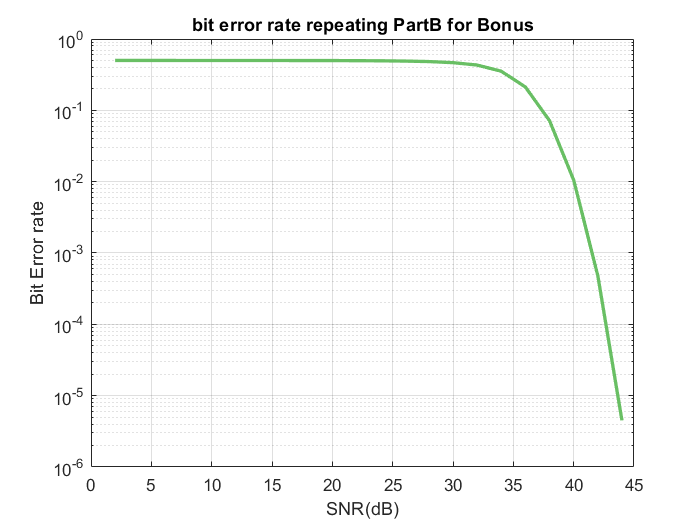

plot_enhanced(2:2:60, bonus_ber, "SNR(dB)", "Bit Error rate", "bit error rate repeating PartB for Bonus")

The pilot signal is placed as part of the beginning of the initial and final headers in the OFDM message, and due to the specificity of these signals in the receiver (by default or passing it as an argument), the receiver is constantly correlating between signals. Received and pilot signal. If no message is sent, this correlation will remain a small, insignificant and relatively constant value due to receiving random noise. However, if a signal is sent, the beginning of which is marked with a pilot signal, due to the peak of this correlation, the index in which the correlation is peaked can be specified as the beginning of the header (and practically the beginning of the message). 

since we are getting correlation of pilot with incoming signal, incoming signal does have pilot sequence in it how ever it is noisy, though, by comvolving, the peak will be appeared systematically. it is representation of incoming signal begining point.